test script for violin/ dabest plot

Try to set up violin plot settings so looks like pretty dabest python

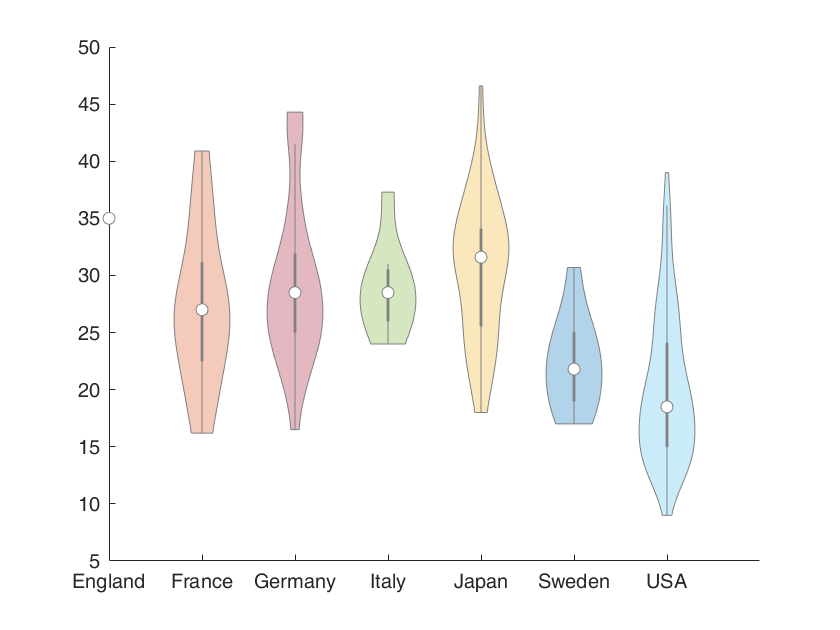

load carbig MPG Origin
Origin = cellstr(Origin);
figure
vs = violinplot(MPG, Origin, 'ShowData',false);

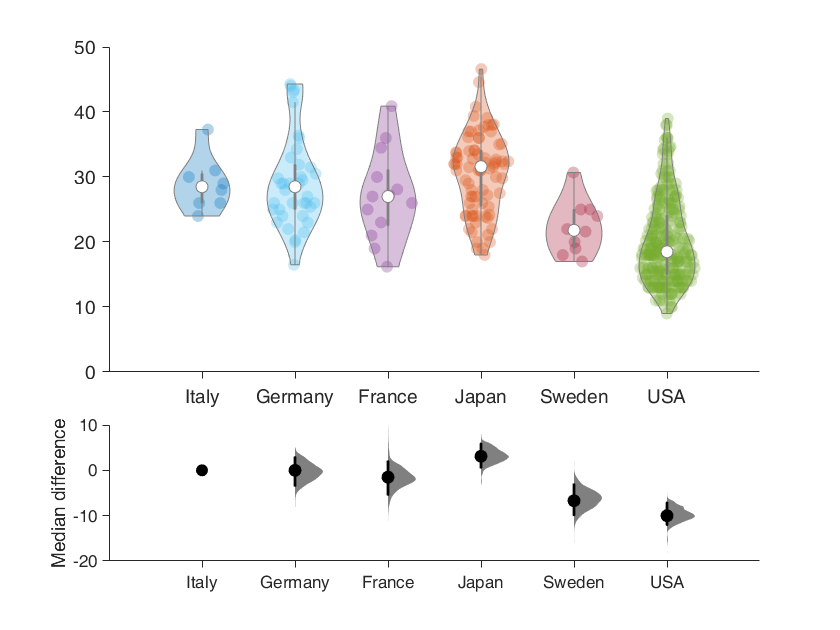

stats1 = 11×4 table
            Group            Value          CIs            N 
    _____________________    _____    ________________    ___

    'Italy'                  28.5         26        31      8
    'Germany'                28.5         26      29.9     39
    'France'                   27         23      31.3     14
    'Japan'                  31.6       29.5      32.4     79
    'Sweden'                 21.8         19        25     11
    'USA'                    18.5         18      19.4    254
    'Germany minus Italy'       0      -4.05         3    NaN
    'France minus Italy'     -1.5       -6.5      3.75    NaN
    'Japan minus Italy'       3.1       -0.1         6    NaN
    'Sweden minus Italy'     -6.7      -10.5        -2    NaN
    'USA minus Italy'         -10     -12.65        -7    NaN


h = struct with fields:
    fig: [1×1 Figure]
    ax1: [1×1 Axes]
     v1: [1×6 Violin]
    ax2: [1×1 Axes]
     v2: [1×6 DabestViolin]



%dabest freaks out at empty args
Origin2= Origin;
MPG2 = MPG;
Origin2(strcmp(Origin,'England'))=[];
MPG2(strcmp(Origin,'England'))=[];
figure
%grouporder specifies what everything is referenced against so important
grouporder={'Italy','Germany','France','Japan','Sweden', 'USA'};
[stats1 h]=violinplusdabest(MPG2, Origin2,grouporder)

figure
%grouporder specifies what everything is referenced against so important
grouporder={'France','Japan','Sweden', 'USA','Italy','Germany'};
[stats2 h]=violinplusdabest(MPG2, Origin2,grouporder)

Error using statmeddiff
Too many output arguments.

Error in violinplusdabest (line 6)
[stats, bootDiff_data, bootDiff_name, bootDiff_order stats_delta delta_name_plot]=statmeddiff(cats, data,nBoot,grouporder);